a = -1;
b = 1;
degree = 3;

point = 1/4;
x_nodes = linspace(-1, 1, degree+1);
xi = linspace(-1, 1, 100);

f = @(x) exp(x);
f_nodes = f(x_nodes);

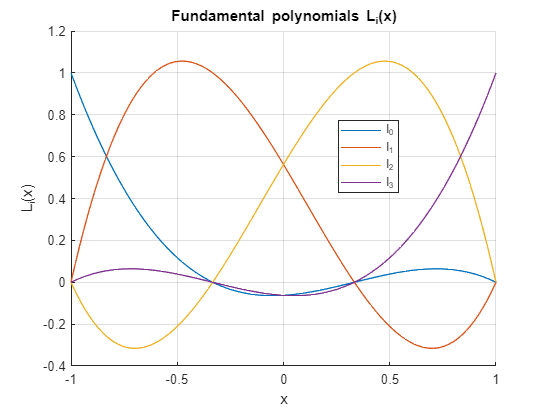

figure;
hold on;
grid on;

for i=1:degree+1
    li = ones(size(xi));
    for j=[1:i-1,i+1:degree+1]
        li = li .* (xi - x_nodes(j)) / (x_nodes(i) - x_nodes(j));
    end
    plot(xi, li, 'DisplayName', ['l_' num2str(i-1)]);
end

title('Fundamental polynomials L_i(x)')
xlabel('x')
ylabel('L_i(x)')

legend('Location','best');
hold off;

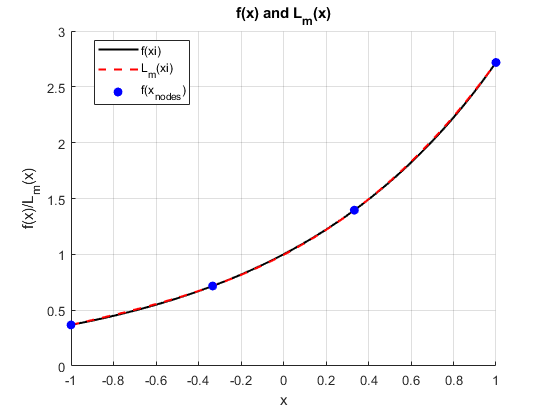

Lm = Lagrange(xi, x_nodes, f_nodes);

figure;
hold on;
grid on;

plot(xi, f(xi), 'k-', 'LineWidth', 1.5, 'DisplayName', 'f(xi)');
plot(xi, Lm, 'r--', 'LineWidth', 1.5, 'DisplayName', 'L_m(xi)');
plot(x_nodes, f_nodes, 'bo', 'MarkerFaceColor', 'b', 'DisplayName', 'f(x_{nodes})');
legend('Location','best');

title ('f(x) and L_m(x)')
xlabel('x');
ylabel('f(x)/L_m(x)');

hold off;

approx_val = Lagrange(point, x_nodes, f_nodes);
abs_err = abs(f(point) - approx_val);

fprintf('Approximation of f(%.2f) = %.16f\n', point, approx_val);

Approximation of f(0.25) = 1.2819532581769031


fprintf('Real value of f(%.2f) = %.16f\n', point, f(point));

Real value of f(0.25) = 1.2840254166877414


fprintf('Absolute error: %.16f\n', abs_err);

Absolute error: 0.0020721585108383


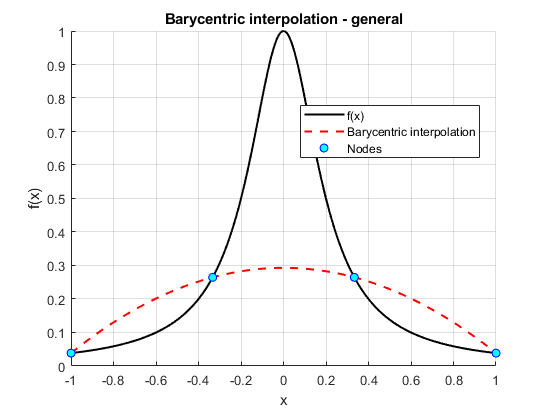

% Runge function (good to test interpolation)
f = @(x) 1 ./ (1 + 25*x.^2);
f_nodes = f(x_nodes);

% Chebyshev nodes #1
x_cheb1 = sort(cos((2*(0:degree)+1)*pi/(2*degree+2))*(b-a)/2 + (a+b)/2);
f_cheb1 = f(x_cheb1);

% Chebyshev nodes #2
x_cheb2 = sort(cos((0:degree)*pi/degree))*(b-a)/2 + (a+b)/2;
f_cheb2 = f(x_cheb2);

% Evaluation points
xi = linspace(a, b, 500);

% Compute barycentric weights for general nodes
c_general = ones(1, degree+1);
for j = 1:degree+1
    for k = [1:j-1, j+1:degree+1]
        c_general(j) = c_general(j) / (x_nodes(j) - x_nodes(k));
    end
end

% Interpolations
B_general = BarycentricInterp(xi, x_nodes, f_nodes, c_general);
B_cheb1 = ChebInterp1(xi, f_cheb1, a, b);
B_cheb2 = ChebInterp2(xi, f_cheb2, a, b);

% Plot General Barycentric Interpolation
figure;
hold on;
grid on;

plot(xi, f(xi), 'k-', 'LineWidth', 1.5, 'DisplayName', 'f(x)');
plot(xi, B_general, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Barycentric interpolation');
plot(x_nodes, f_nodes, 'bo', 'MarkerFaceColor','c', 'DisplayName', 'Nodes');

legend('Location', 'best')
title('Barycentric interpolation - general');
xlabel('x');
ylabel('f(x)');
hold off;

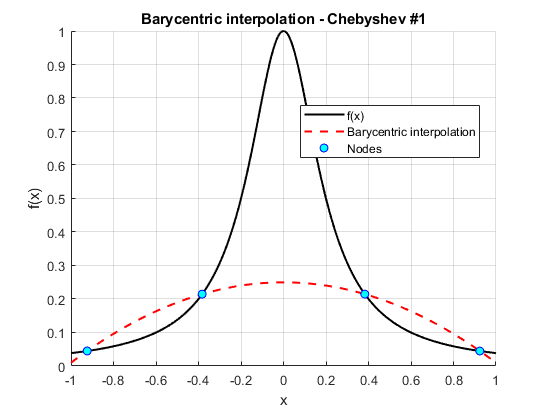


% Plot Chebyshev #1 Barycentric Interpolation
figure;
hold on;
grid on;

plot(xi, f(xi), 'k-', 'LineWidth', 1.5, 'DisplayName', 'f(x)');
plot(xi, B_cheb1, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Barycentric interpolation');
plot(x_cheb1, f_cheb1, 'bo', 'MarkerFaceColor','c', 'DisplayName', 'Nodes');

legend('Location', 'best');
title('Barycentric interpolation - Chebyshev #1');
xlabel('x');
ylabel('f(x)');
hold off;

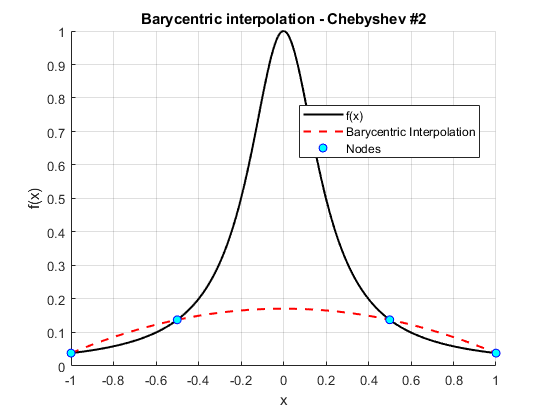


% Plot Chebyshev #2 Barycentric Interpolation
figure;
hold on;
grid on;

plot(xi, f(xi), 'k-', 'LineWidth', 1.5, 'DisplayName', 'f(x)');
plot(xi, B_cheb2, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Barycentric Interpolation');
plot(x_cheb2, f_cheb2, 'bo', 'MarkerFaceColor','c', 'DisplayName', 'Nodes');

legend('Location', 'best');
title('Barycentric interpolation - Chebyshev #2');
xlabel('x');
ylabel('f(x)');
hold off;